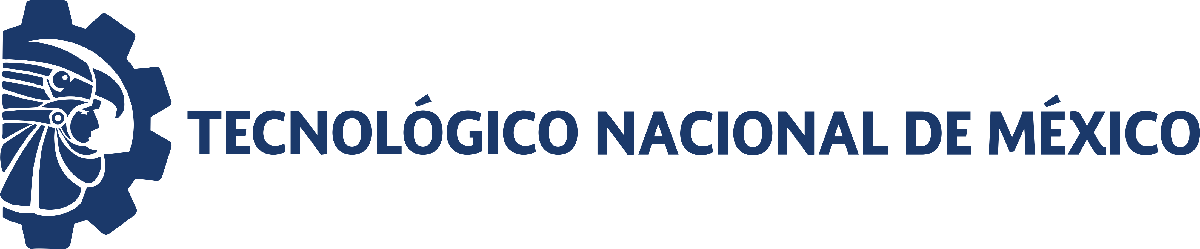                                 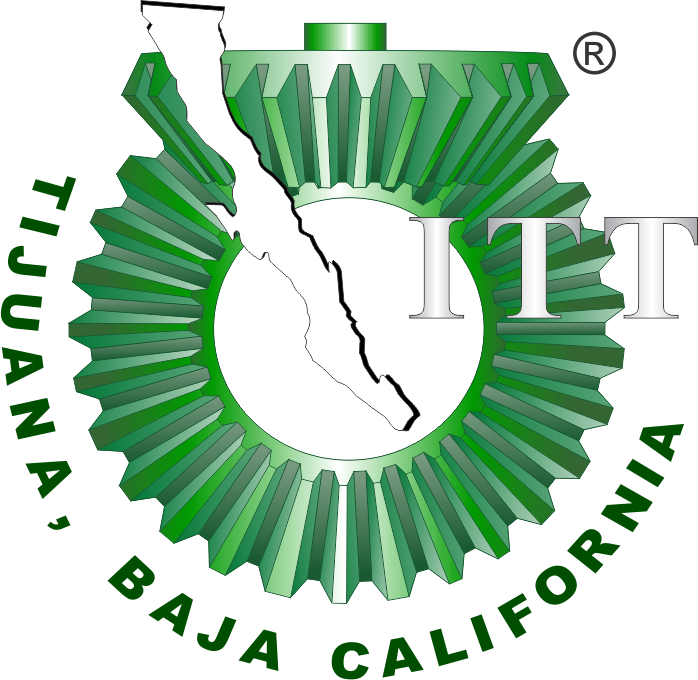

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Práctica: Caos en sistemas biológicos

Comparar métodos de diferencias finitas para solucionar sistemas de ODEs no lineales de primer orden que exhiben diferentes conjuntos compactos invariantes para diferentes valores en sus parámetros y/o condiciones iniciales. El modelo matemático está compuesto por las siguientes tres EDOs de primer orden:


$$\dot x = r_1 x (1-b_1x)-a_{12}xy-a_{13}xz
$$



$$\dot y = r_2y(1-b_2y)-a_{21}xy$$



$$\dot z = (r_3-a_{31})xz-d_3z+\rho_i$$


donde la variable de estado $x\left(t\right)$ representa la población de células anormales o patalógicas, la variable de estado $y\left(t\right)$ la población de células normales o sanas y la variable de estado $z\left(t\right)$ población de células efectoras (citotóxicas o NK); la descripción y valores de los parámetros se presenta a continuación:

$r_1 =1:$ Tasa de crecimiento de las células patológicas.

$b_1 =1:$ Capacidad de carga máxima de las células patológicas.

$a_{12} \in \left\lbrack 0,1\right\rbrack :$ Fracción de células patológicas eliminadas por las células sanas.

$a_{13} =2\ldotp 5:$ Fracción de células patológicas eliminadas por células efectoras.

$r_2 =0\ldotp 6:$ Tasa de crecimiento de las células sanas.

$b_2 =1:$ Capacidad de carga máxima de las células sanas.

$a_{21} =1\ldotp 5:$ Fracción de células sanas eliminadas por las células patológicas.

$r_3 =3:$ Tasa de reclutamiento máximo de células efectoras.

$a_{31} =0\ldotp 3:$ Fracción de células efectoras inactivadas por las células patológicas.

$d_3 =0\ldotp 4:$ Tasa de muerte de las células efectoras.

$\rho_i \left(t\right):$ Tratamiento de inmunoterapia.

Cabe destacar que la dinámica del sistema se localiza en octante no negativo definido por el siguiente dominio:


$$\mathbf{R}_{+,0}^{3}=\left\{ x\left( t\right) \geq 0,y\left( t\right) \geq 0,z\left( t\right) \geq 0\right\}$$


El sistema exhibe diferentes dinámicas para distintos valores del parámetro de bifurcación $a_{12}$, como se indica a continuación:

- Un atractor caótico con $a_{12} =1$, en el intervalo de tiempo $t\in \left\lbrack 0,1000\right\rbrack$ y las condiciones iniciales:$\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 555,0\ldotp 148,0\ldotp 172\right)\ldotp$

- Una órbita periódica con $a_{12} =0\ldotp 9$, en el intervalo de tiempo $t\in \left\lbrack 0,500\right\rbrack$ y las condiciones iniciales: $\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 254781,0\ldotp 115167,0\ldotp 600527\right)\ldotp$

- Un ciclo límite interno con $a_{12} =0\ldotp 8$, en el intervalo de tiempo $t\in \left\lbrack 0,500\right\rbrack$ y las condiciones iniciales: $\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 2,0\ldotp 6,0\ldotp 1\right)\ldotp$

- Un ciclo límite externo con $a_{12} =0\ldotp 75$, en el intervalo de tiempo $t\in \left\lbrack 0,500\right\rbrack$ y las condiciones iniciales: $\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 4,0\ldotp 2,0\ldotp 4\right)\ldotp$

- Convergencia hacia un punto de equilibrio con $a_{12} =0\ldotp 5$, en el intervalo de tiempo $t\in \left\lbrack 0,500\right\rbrack$ y las condiciones iniciales: $\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 5,0\ldotp 5,0\ldotp 4\right)\ldotp$

[Figura representativa del sistema elaborada en BioRender] 

Figura. Generar la figura del sistema presa-depredador con [https://bioart.niaid.nih.gov/](https://bioart.niaid.nih.gov/) o [https://www.biorender.com/](https://www.biorender.com/).

## Referencias

[1] Valle, Paul A., *Syllabus para Biología de Sistemas y Gemelos Digitales*, Tecnológico Nacional de México / Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2026. Permalink: [https://biomath.xyz/course/](https://biomath.xyz/course/) 

[2] Itik, M., & Banks, S. P. (2010). Chaos in a three-dimensional cancer model. *international Journal of bifurcation and chaos*, *20*(01), 71-79. [https://doi.org/10.1142/S0218127410025417](https://doi.org/10.1142/S0218127410025417)

[3] Bryan, Kurt. *Differential equations: A toolbox for modeling the world*. Simiode, 2022. Permalink: [https://www.simiode.org/resources/8307](https://www.simiode.org/resources/8307) 

## Información general

[Foto]

Nombre del alumno: Flores Gonzalez Emmanuel Alejandro

Número de control: M26210085

Correo institucional: m26210085@tectijuana.edu.mx

Asignatura: Modelado Matematico

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')

## Comparacion de metodos numericos:Atractor Caotico

D = getdata('chaos'); f0 = D.f0; par = D.par;
dt = 1e-3;
tend = 1000;
rhoi_0 = zeros(round(tend/dt)+1,1);

### Euler

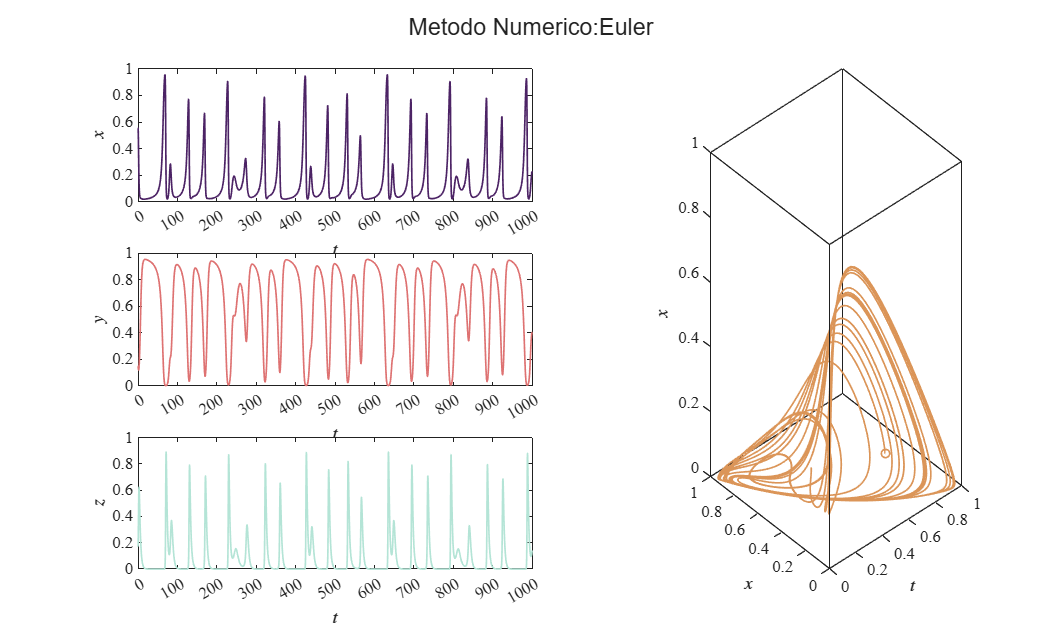

method = 'Euler';
[t,x,y,z] = odesolver(method,f0,par,rhoi_0,tend,dt);
plotEDOs(t,x,y,z); sgtitle(['Metodo Numerico:', method]);...
    exportgraphics(gcf,[method, '_Chaos.pdf'],'contentType','vector')

### Heun

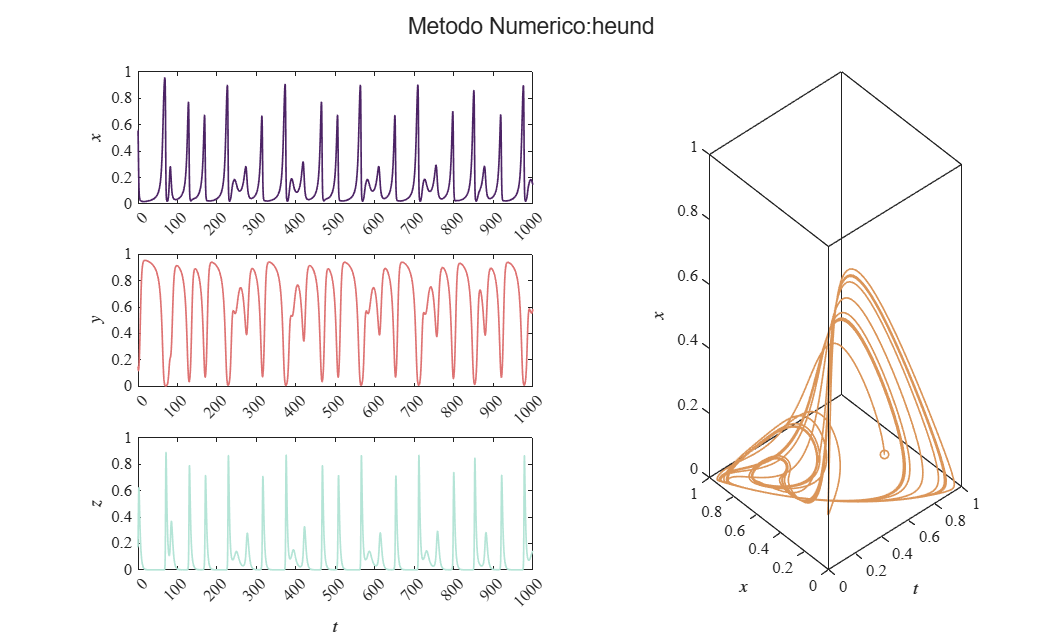

method = 'heund';
[t,x,y,z] = odesolver(method,f0,par,rhoi_0,tend,dt);
plotEDOs(t,x,y,z); sgtitle(['Metodo Numerico:', method]);...
    exportgraphics(gcf,[method, '_Chaos.pdf'],'contentType','vector')

### Runge-Kutta

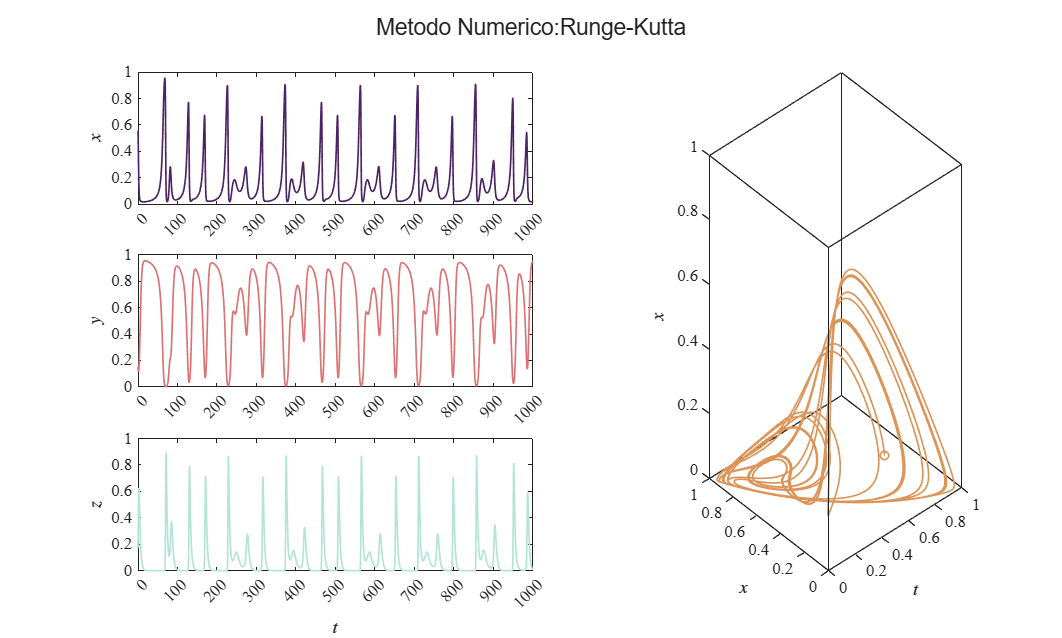

method = 'Runge-Kutta';
[t,x,y,z] = odesolver(method,f0,par,rhoi_0,tend,dt);
plotEDOs(t,x,y,z); sgtitle(['Metodo Numerico:', method]);...
    exportgraphics(gcf,[method, '_Chaos.pdf'],'contentType','vector')

### Orbita periodica

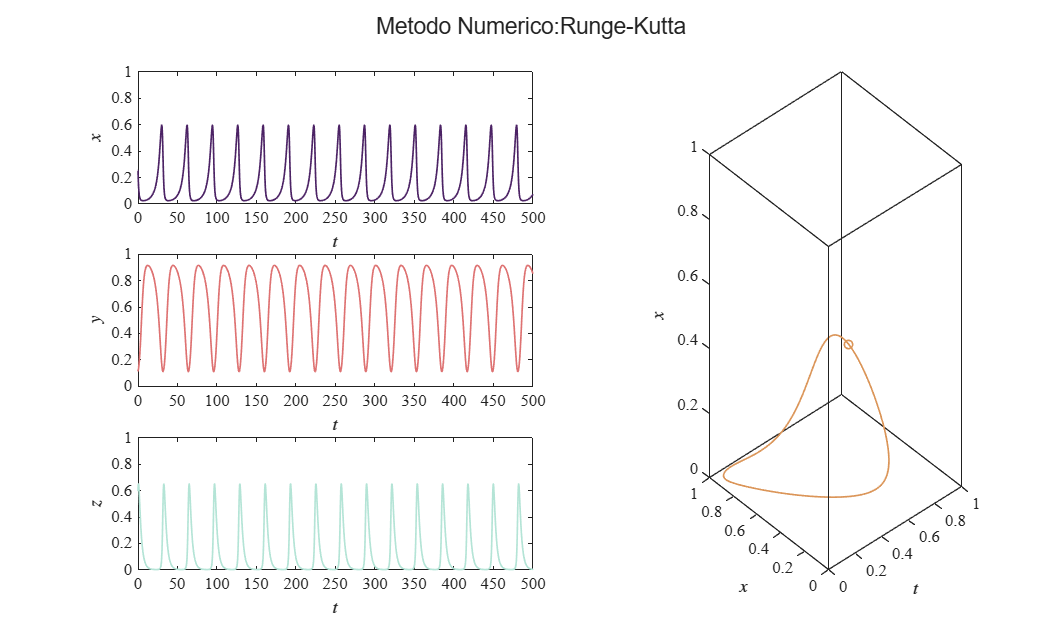

D = getdata('orbit'); f0 = D.f0; par = D.par;
dt = 1e-4;
tend = 500;
rhoi_0 = zeros(round(tend/dt)+1,1);
method = 'Runge-Kutta';
[t,x,y,z] = odesolver(method,f0,par,rhoi_0,tend,dt);
plotEDOs(t,x,y,z); sgtitle(['Metodo Numerico:', method]);...
    exportgraphics(gcf,[method, '_orbit.pdf'],'contentType','vector')

### Ciclo limite interno

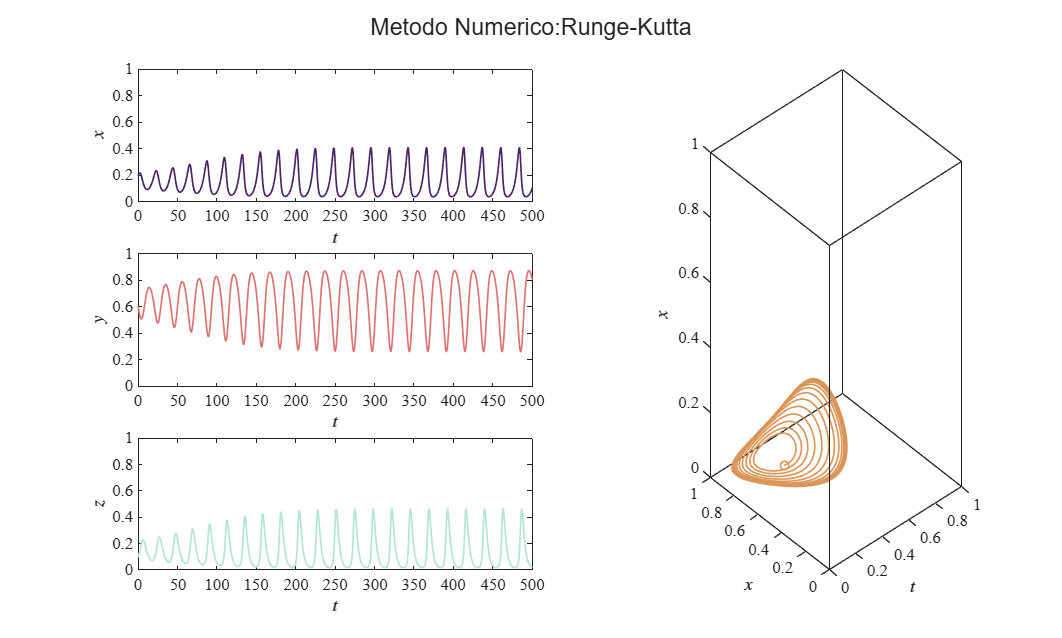

D = getdata('cyclei'); f0 = D.f0; par = D.par;
dt = 1e-4;
tend = 500;
rhoi_0 = zeros(round(tend/dt)+1,1);
method = 'Runge-Kutta';
[t,x,y,z] = odesolver(method,f0,par,rhoi_0,tend,dt);
plotEDOs(t,x,y,z); sgtitle(['Metodo Numerico:', method]);...
    exportgraphics(gcf,[method, '_cycleI.pdf'],'contentType','vector')

### Ciclo limite externo

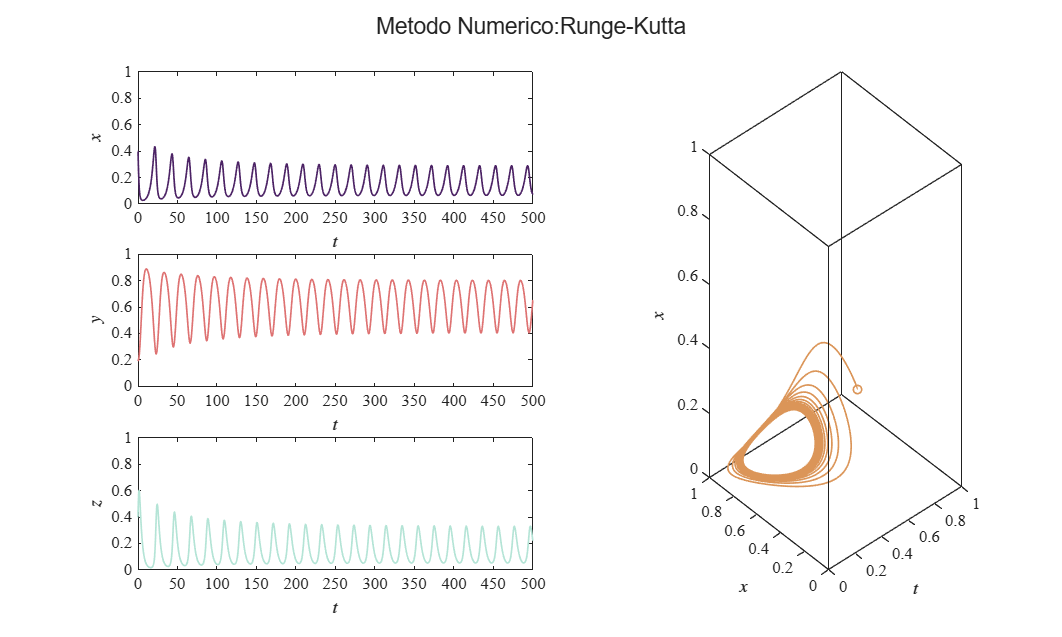

D = getdata('cyclee'); f0 = D.f0; par = D.par;
dt = 1e-4;
tend = 500;
rhoi_0 = zeros(round(tend/dt)+1,1);
method = 'Runge-Kutta';
[t,x,y,z] = odesolver(method,f0,par,rhoi_0,tend,dt);
plotEDOs(t,x,y,z); sgtitle(['Metodo Numerico:', method]);...
    exportgraphics(gcf,[method, '_cycleE.pdf'],'contentType','vector')

### Punto de equilibrio

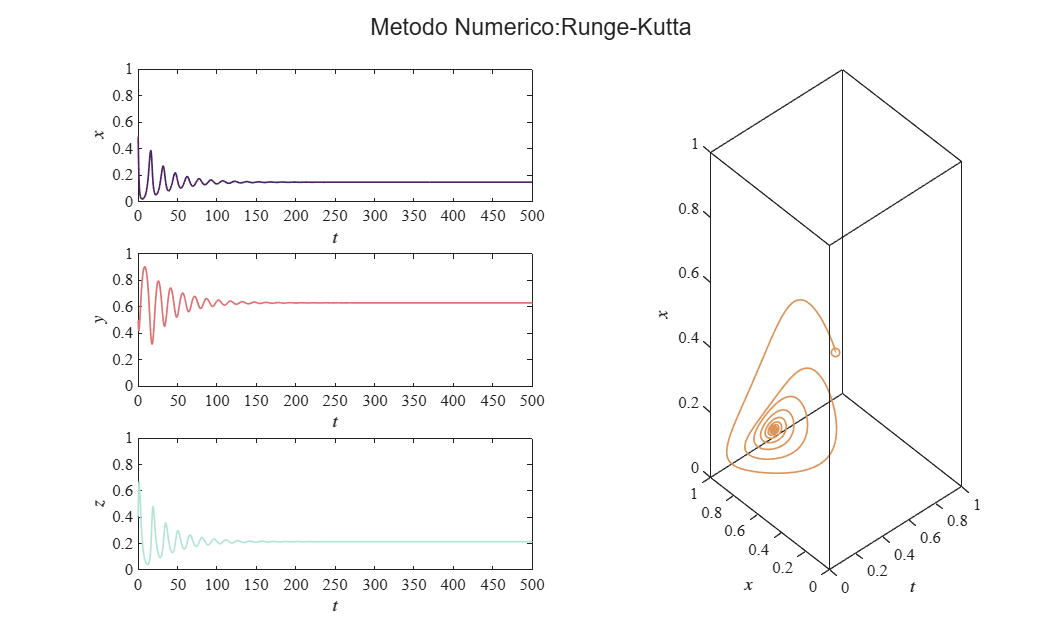

D = getdata('equilibrium'); f0 = D.f0; par = D.par;
dt = 1e-4;
tend = 500;
rhoi_0 = zeros(round(tend/dt)+1,1);
method = 'Runge-Kutta';
[t,x,y,z] = odesolver(method,f0,par,rhoi_0,tend,dt);
plotEDOs(t,x,y,z); sgtitle(['Metodo Numerico:', method]);...
    exportgraphics(gcf,[method, '_Equilibrium.pdf'],'contentType','vector')

## Funciones

### Metodos numericos

function [t,x,y,z] = odesolver (method,f0,par,rhoi,tend,dt)
   method = lower(strtrim(method));

   x0 = f0(1); y0 = f0(2); z0 = f0(3);
   r1 = par(1); b1 = par(2); a12 = par(3); a13 = par(4);
   r2 = par(5); b2 = par (6); a21 = par(7);
   r3 = par(8); a31 = par (9); d3 = par(10);
   
   n = round (tend/dt);
   t = (0:dt:tend)';
   x = zeros(length(t),1); x(1) = x0;
   y = zeros(length(t),1); y(1) = y0;
   z = zeros(length(t),1); z(1) = z0;

   for i = 1:n
       switch method
           case "euler"
               [fx,fy,fz] = f(x(i),y(i),z(i),rhoi(i));
               x(i+1) = x(i) + fx*dt;
               y(i+1) = y(i) + fy*dt;
               z(i+1) = z(i) + fz*dt;
           case "heund"
               [fx,fy,fz] = f(x(i),y(i),z(i),rhoi(i));
               xn = x(i) + fx*dt;
               yn = y(i) + fy*dt;
               zn = z(i) + fz*dt;
               [fxn,fyn,fzn] = f(xn,yn,zn,rhoi(i));
               x(i+1) = x(i) + (fx +fxn)*dt/2;
               y(i+1) = y(i) + (fy +fyn)*dt/2;
               z(i+1) = z(i) + (fz +fzn)*dt/2;

           case "runge-kutta"
               [k1x,k1y,k1z] = f(x(i),y(i),z(i),rhoi(i));
               [k2x,k2y,k2z] = f(x(i)+k1x*dt/2, y(i)+k1y*dt/2, z(i)+k1z*dt/2, rhoi(i));
               [k3x,k3y,k3z] = f(x(i)+k2x*dt/2, y(i)+k2y*dt/2, z(i)+k2z*dt/2, rhoi(i));
               [k4x,k4y,k4z] = f(x(i)+k3x*dt, y(i)+k3y*dt, z(i)+k3z*dt,rhoi(i));
               x(i+1) = x(i) + (k1x + 2*k2x + 2*k3x +k4x)*dt/6;
               y(i+1) = y(i) + (k1y + 2*k2y + 2*k3y +k4y)*dt/6;
               z(i+1) = z(i) + (k1z + 2*k2z + 2*k3z +k4z)*dt/6;

       end
   end

    function [dx,dy,dz] = f(x,y,z,r)
        dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z;
        dy = r2*y*(1 -b2*y) - a21*x*y;
        dz = (r3 -a31)*x*z - d3*z + r;
    end

    h = 10;%Nota dt >= 1e-1
    t = t(1:1/(h*dt):end);
    x = x(1:1/(h*dt):end);
    y = y(1:1/(h*dt):end);
    z = z(1:1/(h*dt):end);
end

### Soluciones y trayectorias

function plotEDOs(t,x,y,z)
   set (figure(), 'color','w')
   set (gcf, 'units', 'centimeters', 'position',  [1,1,25,15])
   

FS = 10;
   %colorhunt.com
   clrx = [76, 35, 101]/255;
   clry = [222, 114, 114]/255;
   clrz = [180, 228, 214]/255;
   clrxyz = [219, 149, 88]/255;

   subplot (3,6,[1,2,3]); box on; hold on; grid off;
   plot (t,x,'LineWidth',1,'Color',clrx)
   xlabel('$t$','Interpreter','latex','FontSize',FS)
   ylabel('$x$','Interpreter','latex','FontSize',FS)
   xlim([0 inf]); xticks(0:t(end)/10:t(end))
   ylim([0 1]); yticks(0:0.2:1)
   set(gca,'FontNAME', 'Time NEW Roman','fontsize',FS)

   subplot (3,6,[7,8,9]); box on; hold on; grid off;
   plot (t,y,'LineWidth',1,'Color',clry)
   xlabel('$t$','Interpreter','latex','FontSize',FS)
   ylabel('$y$','Interpreter','latex','FontSize',FS)
   xlim([0 inf]); xticks(0:t(end)/10:t(end))
   ylim([0 1]); yticks(0:0.2:1)
   set(gca,'FontNAME', 'Time NEW Roman','fontsize',FS)

   subplot (3,6,[13,14,15]);
   plot (t,z,'LineWidth',1,'Color',clrz)
   xlabel('$t$','Interpreter','latex','FontSize',FS)
   ylabel('$z$','Interpreter','latex','FontSize',FS)
   xlim([0 inf]); xticks(0:t(end)/10:t(end))
   ylim([0 1]); yticks(0:0.2:1)
   set(gca,'FontNAME', 'Time NEW Roman','fontsize',FS)

   subplot (3,6,[5,6,11,12,17,18]); box on; hold on; grid off; view([-42,21])
   ax = gca; ax.BoxStyle = 'full';
   plot3(x,y,z,'-','LineWidth',1,'Color',clrxyz)
   plot3(x(1),y(1),z(1), 'o', 'LineWidth',1,'MarkerSize',5,'Color',clrxyz)
   xlim([0 1]);   xticks(0:0.2:1)
   ylim([0 1]);   yticks(0:0.2:1)
   zlim([0 1]);   zticks(0:0.2:1)
   xlabel('$t$','Interpreter','latex','FontSize',FS)
   ylabel('$x$','Interpreter','latex','FontSize',FS)
   zlabel('$x$','Interpreter','latex','FontSize',FS)
   set(gca,'FontNAME', 'TimeNewRoman', 'FontSize',FS)

end


### Parametros y condiciones inciales

function D = getdata(dynamics)
r1 = 1;   b1=1;   a12 = 1;  a13 = 2.5;
r2 = 0.6; b2= 1;  a21 = 1.5;
r3 = 3;   a31 = 0.3; d3 = 0.4;

if dynamics == "chaos"
    a12 = 1;
    f0 = [0.555,0.148,0.172]; %[x0,y0,z0]
elseif dynamics == "orbit"
    a12 = 0.9;
    f0 = [0.254781,0.115167,0.600527];
elseif dynamics == "cyclei"
    a12 = 0.8;
    f0 = [0.2,0.6,0.1];
elseif dynamics == "cyclee"
    a12 = 0.75;
    f0 = [0.4,0.2,0.4];
elseif dynamics == "equilibrium"
    a12 = 0.5;
    f0 = [0.5,0.5,0.4];
end
par =[r1,b1,a12,a13,r2,b2,a21,r3,a31,d3];
D.par = par;
D.f0 = f0;
end

%par_chaos = [r1,b1,a12,a13,r2,b2,a21,r3,a31,d3];